clc; clear;

% 舊模型若缺少必要資料就自動重訓；完整模型存在時，下次會自動載入。
modelFile = "EEG_CNN_GRU_mixedSess.mat";
forceRetrain = true;
if isfile(modelFile)
    modelInfo = whos("-file", modelFile);
    modelNames = string({modelInfo.name});
    requiredModelVars = ["net","acc","mu","sig","classNames","inputSize"];
    forceRetrain = ~all(ismember(requiredModelVars, modelNames));
end

% ===============================
% (1) 參數設定：資料路徑、切窗、濾波、通道
% ===============================

%完整21 channels
useCh = ["FC5","FC3","FC1","FCz","FC2","FC4","FC6", ...
        "C5","C3","C1","Cz","C2","C4","C6", ...
        "CP5","CP3","CP1","CPz","CP2","CP4","CP6"];

% 為之後切分準備
dataRoot = "eegmmidb_all";   
winSec   = 1.0;           % 每個 window 幾秒
stride   = 10;            % window 滑動步長(樣本數)
useBandpass = true;       % 是否濾波
bp = [1 40];              % bandpass 頻帶

% ===============================
% (2) 掃描資料夾
% ===============================

subs = dir(fullfile(dataRoot, "S*")); % 找到所有S開頭資料夾
subs = subs([subs.isdir]); % 只留下受試者資料夾

skipSubs = ["S088","S092","S100","S104"]; % 跳過採樣率不同/資料過短者
subNames = string({subs.name});
subs = subs(~ismember(subNames, skipSubs));

numSub = numel(subs); % 人數
assert(numSub > 1, "No subject folders found."); % 若小於一人則報錯
fprintf("Using %d subjects after skipping: %s\n", numSub, strjoin(skipSubs, ", "));

Using 105 subjects after skipping: S088, S092, S100, S104



% ===============================
% (3) 資料存放
% ===============================

cacheFile = sprintf("EEG_%d_stride%d_mixedSess.mat", numSub, stride);
XTrain = {}; % 用 array 存放每個EEG Window (矩陣)
YTrain = categorical(); % 存放是哪個人
XTest  = {};
YTest  = categorical();
XValSess = {};
YValSess = categorical();


%判斷是否有資料夾了
if isfile(cacheFile)
   fprintf("Loading cached windows: %s\n", cacheFile);
   load(cacheFile, "XTr4","YTr","XVal4","YVal","XTest4","YTest","XTr");

   % 舊 cache 沒有 mu/sig 時，由原始訓練 windows 補算，避免重新讀 EDF。
   cacheInfo = whos("-file", cacheFile);
   cacheNames = string({cacheInfo.name});
   if all(ismember(["mu","sig"], cacheNames))
       load(cacheFile, "mu", "sig");
   else
       XTrRaw4 = single(cat(4, XTr{:}));
       mu  = mean(XTrRaw4, [2 4]);
       sig = std(XTrRaw4, 0, [2 4]);
       sig(sig < 1e-6) = 1e-6;
       clear XTrRaw4
   end
else


% 資料準備：讀 EDF -> 依 annotation 切段 -> 滑動切窗 -> 建立 label
for si = 1:numSub % 幾個人跑幾遍
   sid = string(subs(si).name); % 轉成string語法，才可以在fullfile直接加上去
   sdir = fullfile(dataRoot, sid); % 組成路徑(自動用正確的斜線組成)
   % 獲得完整路徑


   % 三個檔案的用法：2 train + 1 test（跨 session）
   trainFiles = [fullfile(sdir, sid+"R04.edf"), fullfile(sdir, sid+"R08.edf")];
   testFiles  = [fullfile(sdir, sid+"R12.edf")];


   % 產生 train windows
   for f = trainFiles
       % C方案：先切時間塊(train/val) + gap，再做sliding windows（避免重疊洩漏）
       splitRatio = 0.7;   % 60% train, 40% val
       gapFactor  = 0.2;     % gap = winLen * gapFactor

       winsTr  = edf_to_windows_split(f, useCh, winSec, stride, useBandpass, bp, "train", splitRatio, gapFactor);
       winsVal = edf_to_windows_split(f, useCh, winSec, stride, useBandpass, bp, "val",   splitRatio, gapFactor);

       XTrain = [XTrain; winsTr]; %#ok<AGROW>
       YTrain = [YTrain; repmat(categorical(sid), numel(winsTr), 1)]; %#ok<AGROW>

       XValSess = [XValSess; winsVal]; %#ok<AGROW>
       YValSess = [YValSess; repmat(categorical(sid), numel(winsVal), 1)]; %#ok<AGROW>
   end

   % 產生 test windows
   for f = testFiles
       % R12 固定只給 test（avoid leakage）
       [wins, ~] = edf_to_windows_split(f, useCh, winSec, stride, useBandpass, bp, "all", 0.8, 1);
       XTest = [XTest; wins]; %#ok<AGROW>
       YTest = [YTest; repmat(categorical(sid), numel(wins), 1)]; %#ok<AGROW>
   end


   fprintf("Done %s\n", sid);
end


fprintf("Train windows: %d | Valid windows : %d | Test windows: %d\n", numel(XTrain), numel(XValSess), numel(XTest));


XTr  = XTrain;   YTr  = YTrain;
XVal = XValSess; YVal = YValSess;

% ===============================
% (4)轉成 trainNetwork 可用的格式(4D)
% ===============================

% C x T x 1 x numWindows
XTr4  = single(cat(4, XTr{:})); % 疊成4D、從double變成single -> 32 bit float
XVal4 = single(cat(4, XVal{:}));
XTest4 = single(cat(4, XTest{:}));

% ------ 用訓練集統計量做 per-channel normalization ------
mu  = mean(XTr4, [2 4]);
sig = std(XTr4, 0, [2 4]);
sig(sig < 1e-6) = 1e-6;

XTr4   = (XTr4  - mu) ./ sig;
XVal4  = (XVal4 - mu) ./ sig;
XTest4 = (XTest4- mu) ./ sig;


save(cacheFile, ...
       "XTr4","YTr","XVal4","YVal","XTest4","YTest", ...
       "XTr","useCh","winSec","stride","useBandpass","bp", ...
       "mu","sig", "-v7.3"); % 一併保存正規化參數與前處理設定
fprintf("Saved cache: %s\n", cacheFile);

end

Loading cached windows: EEG_105_stride10_mixedSess.mat


## CNN 層

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:38 |        0.00% |        0.66% |       5.1367 |       4.8064 |          0.0020 |
|       1 |          50 |       00:01:08 |        3.12% |        5.09% |       4.4668 |       4.2665 |          0.0020 |
|       1 |         100 |       00:01:32 |        1.56% |        6.99% |       4.2638 |       4.0071 |          0.0020 |
|       1 |         150 |       00:01:54 |       10.94% |       10.08% |       3.9523 |       3.8221 |          0.0020 |
|       

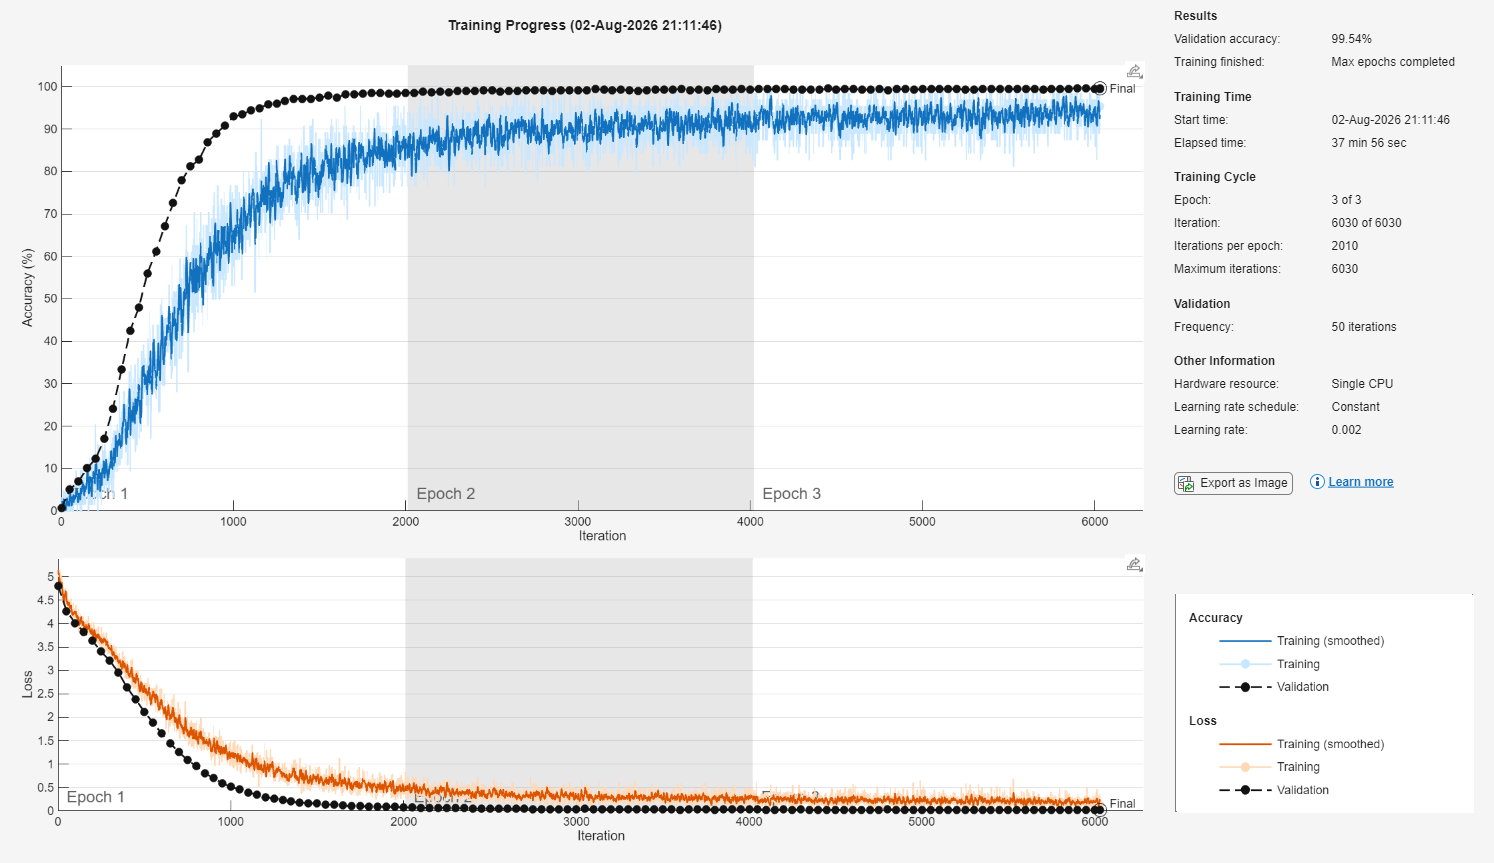

Test Accuracy = 96.70%


Saved complete trained model: EEG_CNN_GRU_mixedSess.mat


% ===============================
% (5) 建 CNN 模型
% ===============================

inputSize  = size(XTr{1});               % [channels, winLen, 1]
numClasses = numel(categories(YTr));

layers = [
    imageInputLayer(inputSize, "Normalization","none", "Name","conv2d_input")

    % --- Conv Block 1 ---
    convolution2dLayer([2 5], 21, "Padding",[0 0 0 0], "Stride",[1 1], "Name","conv1")
    batchNormalizationLayer("Name","bn1")
    reluLayer("Name","relu1")

    % --- Conv Block 2 ---
    convolution2dLayer([2 5], 20, "Padding",[0 0 0 0], "Stride",[1 1], "Name","conv2")
    batchNormalizationLayer("Name","bn2")
    reluLayer("Name","relu2")

    maxPooling2dLayer([1 10], "Stride",[1 8], "Name","max_pooling1")

    % --- Conv Block 3 ---
    convolution2dLayer([2 5], 15, "Padding",[0 0 0 0], "Stride",[1 1], "Name","conv3")
    batchNormalizationLayer("Name","bn3")
    reluLayer("Name","relu3")

    % --- 2D MaxPool (same as your pool1) ---
    maxPooling2dLayer([1 10], "Stride",[1 8], "Name","max_pooling2")

    % --- Reshape SSCB -> CTB : (H,W,C,B) -> (C, B, H*W) = 15 x B x 324 ---
    functionLayer(@(X) dlarray(reshape(permute(stripdims(X), [3, 1, 2, 4]), 15, [], size(X,4)), 'CTB'), ... 
    "Name", "reshape", "Formattable", true)

    % --- GRU ---
    % 明確指定 before-multiplication，與下方手算 GRU/未來 RTL 的 Uh*(r.*h) 一致。
    gruLayer(9, "OutputMode", "sequence", ...
        "ResetGateMode", "before-multiplication", "Name", "gru")

    % --- 1D MaxPool over time: 324T -> 24T (pool=16, stride=13) ---
    %maxPooling1dLayer(16, "Stride",13, "Name","max_pooling1d")

    dropoutLayer(0.2, "Name","drop_1")

    % functionLayer(@(X) dlarray(reshape(permute(stripdims(X), [1, 3, 2]), [], size(X,2)), 'CB'), ...
    %     "Name", "flatten")

    functionLayer(@(X) dlarray( ...
    reshape(permute(stripdims(X), [1 3 2]), ...   % C×B×T -> C×T×B
           size(X,1)*size(X,3), size(X,2)), ...   % (C*T) × B
    'CB'), ...
    "Name","flatten_reshape","Formattable",true)

    %flattenLayer("Name","flat")
    fullyConnectedLayer(40, "Name","fc_1")
    reluLayer("Name","relu_fc")
    batchNormalizationLayer("Name","bn_2")

    dropoutLayer(0.5, "Name","drop_out")

    fullyConnectedLayer(numClasses, "Name","fc_out")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","cls")
];

opts = trainingOptions("adam", ...
    "MaxEpochs", 3, ...
    "MiniBatchSize", 64, ...
    "InitialLearnRate", 0.002, ... 
    "Shuffle","every-epoch", ...
    "ValidationData",{XVal4,YVal}, ...
    "Plots","training-progress", ...
    "Verbose",true);

% 可選擇重新訓練或直接載入；避免每次 Run All 都重新訓練。
if ~forceRetrain && isfile(modelFile)
    savedModel = load(modelFile);
    net = savedModel.net;
    acc = savedModel.acc;
    fprintf("Loaded trained model: %s\n", modelFile);
else
    rng(42, "twister"); % 固定亂數，讓重新訓練結果較容易重現。
    net = trainNetwork(XTr4, YTr, layers, opts);

    %% Test accuracy
    YPred = classify(net, XTest4);
    acc = mean(YPred == YTest);
    fprintf("Test Accuracy = %.2f%%\n", acc*100);

    classNames = categories(YTr);
    trainedLayers = net.Layers;
    save(modelFile, "net", "layers", "trainedLayers", ...
        "useCh","winSec","stride","useBandpass","bp", ...
        "mu","sig","classNames","inputSize","numClasses", ...
        "opts","acc", "-v7.3"); % 保存下次免訓練所需的完整資料
    fprintf("Saved complete trained model: %s\n", modelFile);
end


analyzeNetwork(layerGraph(layers))

## 切分 Function

% 切分區塊
function [wins, fs] = edf_to_windows_split(edfFile, useCh, winSec, stride, useBandpass, bp, mode, splitRatio, gapFactor)
   % winLen = WinSec * fs : 160 = 1 * 160
   % t = stride / fs : 10 / 160 ~= 0.0625 s 每 取一個window
   % N 總sample數， N = time * fs : 125 * 160 = 2000

   % 讀取 EDF
   info = edfinfo(edfFile);
   tt   = edfread(edfFile);  % timetable
   ann = info.Annotations;

   % 取得fs = ~160
   ns = info.NumSamples;
   fsVec = ns / seconds(info.DataRecordDuration);
   if numel(unique(fsVec)) ~= 1
       error("EDF signals have different sampling rates.");
   end
   fs = fsVec(1);

   % ====== 找到 useCh 對應的欄位 ======
   varNames = string(tt.Properties.VariableNames);

   % 正規化
   vnNorm = lower(erase(varNames, "_")); % 所有通道，小寫並去掉_
   ucNorm = lower(erase(useCh, "_")); % 我設定的通道
   % 建陣列存放索引位置
   idxCh = zeros(1, numel(useCh));

   % ====== 找到我需要的通道，去除不要的通道 ======

   for i = 1:numel(useCh) % 每個通道跑一次
       hit = find(vnNorm == ucNorm(i), 1);
       if isempty(hit)
           error("Channel %s not found in EDF variables.", useCh(i));
       end
       idxCh(i) = hit; % 要取通道索引
   end

   sigCell = tt{:, idxCh};   % 把 timetable 的資料取出成數值矩陣，N

   if iscell(sigCell)
       X = cell2mat(sigCell);        % [N x channels]
   else
       X = sigCell;
   end

   % ====== bandpass 濾波 ======
   if useBandpass
       X = bandpass(X, bp, fs); % 保留 1~40 HZ
   end

   labels = upper(strtrim(string(ann.Annotations)));  % T0 / T1 / T2 (轉成大寫)
   onset  = seconds(ann.Onset); % 每段從第幾秒開始
   dur    = seconds(ann.Duration); % 每段持續多久

   % ====== sliding window ======
   winLen = round(winSec * fs);  % samples，1*160
   if winLen < 2 % 切出窗口太小
       error("winLen too small");
   end

   wins = cell(0,1); % 每切一個window就存放進去
   k = 1;

   targetFs = 160;
    if abs(fs - targetFs) > 1e-6
        error("Sampling rate is not 160 Hz: %s (fs = %.4f)", edfFile, fs);
    end

   gapSamp = gapFactor * winLen;

   for i = 1:numel(labels)
       if labels(i) == "T2"
           continue;   % 去除 T2
       end

       stSamp = floor(onset(i) * fs) + 1; %第幾秒開始 * fs = 開始點在第幾個sample
       edSamp = stSamp + floor(dur(i) * fs) - 1; % 最後一個點位置

       stSamp = max(stSamp, 1);
       edSamp = min(edSamp, size(X,1));

       if edSamp - stSamp + 1 < winLen % 160
           continue;   % 該段不足一個 window
       end

       seg = X(stSamp:edSamp, :);  % seg: [N x channels] = 一段有幾個sample

       segLen = size(seg,1);

       if mode == "all"
           a = 1;
           b = segLen;
       else
           cut = floor(splitRatio * segLen);
           if mode == "train"
               a = 1;
               b = cut - gapSamp;
           elseif mode == "val"
               a = cut + gapSamp;
               b = segLen;
           else
               error("Unknown mode");
           end
       end

       a = max(a, 1);
       b = min(b, segLen);

       if b - a + 1 < winLen
           continue;
       end

       subSeg = seg(a:b, :);

       for st = 1:stride:(size(subSeg,1)-winLen+1) % 從第一個到最後一個sample, 一次跳stride
       w = subSeg(st:st+winLen-1, :);  % [winLen x channels]
       w = w.';                     % -> [channels x winLen]

       % ====== per-window z-score (channel-wise) ======
       % 平均值變0 標準差變1
       w = single(w);

       wins{k,1} = reshape(w, size(w,1), size(w,2), 1); % [C x T x 1]
       k = k + 1;
       end
   end

   if isempty(wins)
       error("No windows extracted after removing T2.");
   end
end

## Quantize

% ============================================================
% (A) PTQ 設定
% ============================================================

% 改對應名稱

q.total_bits = 16;               % 設定整體固定點總位元數 = 16-bit (包含 sign bit)
q.mode       = "floor";          % 截斷（模擬硬體右移直接捨去小數）
probeAct = ["conv1","conv2","conv3","bn1","bn2","bn3",...
    "relu1","relu2","relu3","max_pooling1","max_pooling2",...
    "fc_1","fc_out","flatten_reshape","bn_2","relu_fc"];
% 指定要分析哪些層的 activation，之後會幫這些層決定小數位 Fa

Nprof = min(200, size(XTr4,4));  
% 只用最多前200筆資料來做 profiling（避免全部資料太慢）

Xprof = XTr4(:,:,:,1:Nprof);     
% 取出前200筆資料作分析（浮點資料）

% ============================================================
% (B) 決定每層小數位(判斷輸入輸出需要多少)
% ============================================================

fprintf("\n=== Profiling activations ===\n");


=== Profiling activations ===


F_act = struct(); % 存每層的Fa（小數位數）

[~, Fa_in, ~] = ComputeQuantBits(Xprof);
% 計算輸入資料需要多少小數位（Fa_in）

fprintf("Fa(input) = %d\n", Fa_in);

Fa(input) = 12


% 一般層
for ln = probeAct
    % 取得指定層的浮點 activation 輸出
    A = activations(net, Xprof, ln, "OutputAs","channels"); 
    
    % 根據 activation 的最大值範圍計算小數位
    [~, Fa, ~] = ComputeQuantBits(A);

    % 存到 struct，例如 F_act.relu1 = 11
    F_act.(ln) = Fa;

    fprintf("Fa(%s) = %d\n", ln, Fa);
end

Fa(conv1) = 13
Fa(conv2) = 10
Fa(conv3) = 10
Fa(bn1) = 11
Fa(bn2) = 11
Fa(bn3) = 12
Fa(relu1) = 11
Fa(relu2) = 12
Fa(relu3) = 12
Fa(max_pooling1) = 12
Fa(max_pooling2) = 13
Fa(fc_1) = 13
Fa(fc_out) = 10
Fa(flatten_reshape) = 15
Fa(bn_2) = 12
Fa(relu_fc) = 13


% GRU層



% ============================================================
% (C) 量化權重 + 匯出 .mem(靜態內部權重量化)
% ============================================================

fprintf("\n=== Export weight mem ===\n");


=== Export weight mem ===



outDir = "export_mem"; % 資料夾
if ~exist(outDir,"dir"), mkdir(outDir); end % 判斷是否建立

% ============================================================
% BN量化與匯出
% ============================================================

bnNames = ["bn1", "bn2", "bn3", "bn_2"];

F_bn = struct();

for nm = bnNames
    idx = find(strcmp({net.Layers.Name}, nm), 1);

    assert(~isempty(idx), ...
        "Cannot find BN layer: %s", nm);

    L = net.Layers(idx);

    % 將BN整理成 y = A*x + B
    A = L.Scale ./ sqrt(L.TrainedVariance + L.Epsilon);

    B = L.Offset ...
      - L.TrainedMean .* L.Scale ...
      ./ sqrt(L.TrainedVariance + L.Epsilon);

    % 分別決定A與B的小數位數
    [~, Fa_A, ~] = ComputeQuantBits(A);
    [~, Fa_B, ~] = ComputeQuantBits(B);

    F_bn.(nm).A = Fa_A;
    F_bn.(nm).B = Fa_B;

    A_int = QuantizeToInt( ...
        A, q.total_bits, Fa_A, q.mode);

    B_int = QuantizeToInt( ...
        B, q.total_bits, Fa_B, q.mode);

    % 目前原始程式缺少這兩個WriteMemHex
    WriteMemHex( ...
        fullfile(outDir, nm + "_A.mem"), A_int);

    WriteMemHex( ...
        fullfile(outDir, nm + "_B.mem"), B_int);

    fprintf("%s: FA=%d FB=%d\n", ...
        nm, Fa_A, Fa_B);
end

bn1: FA=11 FB=13
bn2: FA=15 FB=14
bn3: FA=15 FB=14
bn_2: FA=13 FB=12



% ------------------------------
% Conv FC quantize(內部參數)
convFc = ["conv1","conv2","conv3","fc_1","fc_out"]; 

F_w = struct(); 
F_b = struct();
% 分別存每層權重的小數位與bias的小數位

for nm = convFc

    % 找到對應層
    idx = find(strcmp({net.Layers.Name}, nm), 1);      
    L   = net.Layers(idx);

    % 取出浮點權重與偏置
    W = L.Weights;
    b = L.Bias;

    % 計算這層權重需要多少小數位
    [~, Fw, ~] = ComputeQuantBits(W);
    [~, Fb, ~] = ComputeQuantBits(b);

    % 存起來給後面RTL用
    F_w.(nm) = Fw;
    F_b.(nm) = Fb;

    % 真正把浮點轉成 int16 固定點整數
    W_int = QuantizeToInt(W, q.total_bits, Fw, q.mode); 
    b_int = QuantizeToInt(b, q.total_bits, Fb, q.mode);

    % 印出層資訊（檢查用）
    fprintf("%s: Fw=%d Fb=%d | W=%s b=%s\n", ...
        nm, Fw, Fb, mat2str(size(W)), mat2str(size(b)));

    % 寫成 .mem 檔案
    WriteMemHex(fullfile(outDir, nm+"_W.mem"), W_int);
    WriteMemHex(fullfile(outDir, nm+"_b.mem"), b_int);
end

conv1: Fw=15 Fb=15 | W=[2 5 1 21] b=[1 1 21]
conv2: Fw=14 Fb=15 | W=[2 5 21 20] b=[1 1 20]
conv3: Fw=15 Fb=15 | W=[2 5 20 15] b=[1 1 15]
fc_1: Fw=15 Fb=14 | W=[40 162] b=[40 1]
fc_out: Fw=15 Fb=15 | W=[105 40] b=[105 1]


% ------------------------------
% GRU quantize

idx_gru = find(strcmp({net.Layers.Name}, "gru"), 1);
Lgru = net.Layers(idx_gru);

H = Lgru.NumHiddenUnits;

Wgru = Lgru.InputWeights;        % [3H, C]
Ugru = Lgru.RecurrentWeights;    % [3H, H]
bgru = Lgru.Bias;                % 可能是 [3H,1] 或 [3H,2]

% 若 bias 為 [3H,2]，將 input bias 與 recurrent bias 相加
if size(bgru,2) == 2
    bgru = sum(bgru, 2);
end

% 依照你目前手刻層的拆法
Wr = Wgru(1:H, :);
Wz = Wgru(H+1:2*H, :);
Wh = Wgru(2*H+1:3*H, :);

Ur = Ugru(1:H, :);
Uz = Ugru(H+1:2*H, :);
Uh = Ugru(2*H+1:3*H, :);

br = bgru(1:H);
bz = bgru(H+1:2*H);
bh = bgru(2*H+1:3*H);

% 建立 GRU 的量化小數位表
F_gru_w = struct();
F_gru_b = struct();

% ------------------------------
% Input weights
[~, F_gru_w.Wr, ~] = ComputeQuantBits(Wr);
[~, F_gru_w.Wz, ~] = ComputeQuantBits(Wz);
[~, F_gru_w.Wh, ~] = ComputeQuantBits(Wh);

Wr_int = QuantizeToInt(Wr, q.total_bits, F_gru_w.Wr, q.mode);
Wz_int = QuantizeToInt(Wz, q.total_bits, F_gru_w.Wz, q.mode);
Wh_int = QuantizeToInt(Wh, q.total_bits, F_gru_w.Wh, q.mode);

WriteMemHex(fullfile(outDir, "gru_Wr.mem"), Wr_int);
WriteMemHex(fullfile(outDir, "gru_Wz.mem"), Wz_int);
WriteMemHex(fullfile(outDir, "gru_Wh.mem"), Wh_int);

fprintf("gru_Wr: Fw=%d | W=%s\n", F_gru_w.Wr, mat2str(size(Wr)));

gru_Wr: Fw=15 | W=[9 15]


fprintf("gru_Wz: Fw=%d | W=%s\n", F_gru_w.Wz, mat2str(size(Wz)));

gru_Wz: Fw=14 | W=[9 15]


fprintf("gru_Wh: Fw=%d | W=%s\n", F_gru_w.Wh, mat2str(size(Wh)));

gru_Wh: Fw=15 | W=[9 15]



% ------------------------------
% Recurrent weights
[~, F_gru_w.Ur, ~] = ComputeQuantBits(Ur);
[~, F_gru_w.Uz, ~] = ComputeQuantBits(Uz);
[~, F_gru_w.Uh, ~] = ComputeQuantBits(Uh);

Ur_int = QuantizeToInt(Ur, q.total_bits, F_gru_w.Ur, q.mode);
Uz_int = QuantizeToInt(Uz, q.total_bits, F_gru_w.Uz, q.mode);
Uh_int = QuantizeToInt(Uh, q.total_bits, F_gru_w.Uh, q.mode);

WriteMemHex(fullfile(outDir, "gru_Ur.mem"), Ur_int);
WriteMemHex(fullfile(outDir, "gru_Uz.mem"), Uz_int);
WriteMemHex(fullfile(outDir, "gru_Uh.mem"), Uh_int);

fprintf("gru_Ur: Fw=%d | W=%s\n", F_gru_w.Ur, mat2str(size(Ur)));

gru_Ur: Fw=15 | W=[9 9]


fprintf("gru_Uz: Fw=%d | W=%s\n", F_gru_w.Uz, mat2str(size(Uz)));

gru_Uz: Fw=15 | W=[9 9]


fprintf("gru_Uh: Fw=%d | W=%s\n", F_gru_w.Uh, mat2str(size(Uh)));

gru_Uh: Fw=14 | W=[9 9]



% ------------------------------
% Bias
[~, F_gru_b.br, ~] = ComputeQuantBits(br);
[~, F_gru_b.bz, ~] = ComputeQuantBits(bz);
[~, F_gru_b.bh, ~] = ComputeQuantBits(bh);

br_int = QuantizeToInt(br, q.total_bits, F_gru_b.br, q.mode);
bz_int = QuantizeToInt(bz, q.total_bits, F_gru_b.bz, q.mode);
bh_int = QuantizeToInt(bh, q.total_bits, F_gru_b.bh, q.mode);

WriteMemHex(fullfile(outDir, "gru_br.mem"), br_int);
WriteMemHex(fullfile(outDir, "gru_bz.mem"), bz_int);
WriteMemHex(fullfile(outDir, "gru_bh.mem"), bh_int);

fprintf("gru_br: Fb=%d | b=%s\n", F_gru_b.br, mat2str(size(br)));

gru_br: Fb=15 | b=[9 1]


fprintf("gru_bz: Fb=%d | b=%s\n", F_gru_b.bz, mat2str(size(bz)));

gru_bz: Fb=15 | b=[9 1]


fprintf("gru_bh: Fb=%d | b=%s\n", F_gru_b.bh, mat2str(size(bh)));

gru_bh: Fb=15 | b=[9 1]



% 把所有量化參數存起來
% ============================================================
% (C2) Replace network weights with quantized weights
% ============================================================
netQ_weight = net;
layers = netQ_weight.Layers;

% ------------------------------
% Conv / FC replace
for i = 1:length(layers)

    name = layers(i).Name;

    if isfield(F_w, name)

        W = layers(i).Weights;
        b = layers(i).Bias;

        Fw = F_w.(name);
        Fb = F_b.(name);

        W_int = QuantizeToInt(W, q.total_bits, Fw, q.mode);
        b_int = QuantizeToInt(b, q.total_bits, Fb, q.mode);

        layers(i).Weights = double(W_int) / 2^Fw;
        layers(i).Bias    = double(b_int) / 2^Fb;
    end
end

% ------------------------------
% BN replace
bnNames = ["bn1", "bn2", "bn3", "bn_2"];
for nm = bnNames

    idx = find(strcmp({layers.Name}, nm), 1);
    L = layers(idx);

    % 重新取得 fold 後參數
    A = L.Scale ./ sqrt(L.TrainedVariance + L.Epsilon);
    B = L.Offset - (L.TrainedMean .* L.Scale ./ sqrt(L.TrainedVariance + L.Epsilon));

    Fa_A = F_bn.(nm).A;
    Fa_B = F_bn.(nm).B;

    A_int = QuantizeToInt(A, q.total_bits, Fa_A, q.mode);
    B_int = QuantizeToInt(B, q.total_bits, Fa_B, q.mode);

    % TrainedVariance 必須大於 0。
    % 設 mean=0、variance=1，並在 Scale 補回 sqrt(1+epsilon)，
    % 這樣 BN 實際輸出仍精確等於：y = A_q*x + B_q。
    A_q = double(A_int) / 2^Fa_A;
    B_q = double(B_int) / 2^Fa_B;
    layers(idx).Scale = A_q .* sqrt(1 + L.Epsilon);
    layers(idx).Offset = B_q;
    layers(idx).TrainedMean = zeros(size(L.TrainedMean));
    layers(idx).TrainedVariance = ones(size(L.TrainedVariance));
end

% ------------------------------
% GRU replace
idx = find(strcmp({layers.Name}, "gru"), 1);
if ~isempty(idx)

    L = layers(idx);
    H = L.NumHiddenUnits;

    % ---- InputWeights 回寫 ----
    Wgru_q = [ double(Wr_int) / 2^F_gru_w.Wr; ...
               double(Wz_int) / 2^F_gru_w.Wz; ...
               double(Wh_int) / 2^F_gru_w.Wh ];

    % ---- RecurrentWeights 回寫 ----
    Ugru_q = [ double(Ur_int) / 2^F_gru_w.Ur; ...
               double(Uz_int) / 2^F_gru_w.Uz; ...
               double(Uh_int) / 2^F_gru_w.Uh ];

    layers(idx).InputWeights = Wgru_q;
    layers(idx).RecurrentWeights = Ugru_q;

    % ---- Bias 回寫 ----
    % 注意：這裡不能直接用 sum 後的 bgru，因為 network 需要原本的 shape
    % netQ 與輸出的 gru_br/bz/bh.mem 使用完全相同的量化 bias。
    bgru_q = [double(br_int) / 2^F_gru_b.br; ...
              double(bz_int) / 2^F_gru_b.bz; ...
              double(bh_int) / 2^F_gru_b.bh];

    if size(L.Bias,2) == 2
        % before-multiplication 模式下，合併 bias 放第一欄，第二欄設為 0。
        layers(idx).Bias = [bgru_q, zeros(size(bgru_q))];
    else
        layers(idx).Bias = bgru_q;
    end
end

netQ_weight = assembleNetwork(layerGraph(layers));

% 移到所有 F 值都建立完成後才儲存，避免使用尚未存在的變數。
% 同時計算目前 conv_engine.sv / testbench 應使用的 shift。
rtl_shift.conv1.bias = Fa_in + F_w.conv1 - F_b.conv1;
rtl_shift.conv1.out  = Fa_in + F_w.conv1 - F_act.conv1;
rtl_shift.conv2.bias = F_act.relu1 + F_w.conv2 - F_b.conv2;
rtl_shift.conv2.out  = F_act.relu1 + F_w.conv2 - F_act.conv2;
rtl_shift.conv3.bias = F_act.max_pooling1 + F_w.conv3 - F_b.conv3;
rtl_shift.conv3.out  = F_act.max_pooling1 + F_w.conv3 - F_act.conv3;

save(fullfile(outDir,"quant_table.mat"), "q","Fa_in","F_act","F_w","F_b", ...
    "F_bn","F_gru_w","F_gru_b","rtl_shift");

shiftFile = fullfile(outDir,"rtl_conv_shifts.txt");
fidShift = fopen(shiftFile,"w");
assert(fidShift ~= -1, "Cannot open file: %s", shiftFile);
fprintf(fidShift,"conv1 BIAS_SHIFT=%d OUTPUT_SHIFT=%d\n", rtl_shift.conv1.bias, rtl_shift.conv1.out);
fprintf(fidShift,"conv2 BIAS_SHIFT=%d OUTPUT_SHIFT=%d\n", rtl_shift.conv2.bias, rtl_shift.conv2.out);
fprintf(fidShift,"conv3 BIAS_SHIFT=%d OUTPUT_SHIFT=%d\n", rtl_shift.conv3.bias, rtl_shift.conv3.out);
fclose(fidShift);

% ============================================================
% (D) 建立 netQ（在已訓練 net 上插入 quant layer）
% ============================================================

fprintf("\n=== Build quantized net (netQ) ===\n");


=== Build quantized net (netQ) ===


lgraphQ = layerGraph(netQ_weight);
% 把已訓練好的浮點模型轉成 layerGraph（準備插入量化層）
% 插入量化layer
lgraphQ = insertQuantAfter(lgraphQ,"conv2d_input","q_in",      q, Fa_in);
lgraphQ = insertQuantAfter(lgraphQ, "conv1", "q_conv1", q, F_act.conv1); % 提早截斷
lgraphQ = insertQuantAfter(lgraphQ,"bn1",       "q_bn1",   q, F_act.bn1);
lgraphQ = insertQuantAfter(lgraphQ,"relu1",       "q_relu1",   q, F_act.relu1);
lgraphQ = insertQuantAfter(lgraphQ, "conv2", "q_conv2", q, F_act.conv2);
lgraphQ = insertQuantAfter(lgraphQ,"bn2",       "q_bn2",   q, F_act.bn2);
lgraphQ = insertQuantAfter(lgraphQ,"relu2",       "q_relu2",   q, F_act.relu2);
lgraphQ = insertQuantAfter(lgraphQ,"max_pooling1","q_pool1",  q, F_act.max_pooling1);
lgraphQ = insertQuantAfter(lgraphQ, "conv3", "q_conv3", q, F_act.conv3);
lgraphQ = insertQuantAfter(lgraphQ,"bn3",       "q_bn3",   q, F_act.bn3);
lgraphQ = insertQuantAfter(lgraphQ,"relu3",       "q_relu3",   q, F_act.relu3);
lgraphQ = insertQuantAfter(lgraphQ,"max_pooling2","q_pool2",  q, F_act.max_pooling2);
lgraphQ = insertQuantAfter(lgraphQ,"flatten_reshape",       "q_flatten",   q, F_act.flatten_reshape);
lgraphQ = insertQuantAfter(lgraphQ,"fc_1",       "q_fc_1",   q, F_act.fc_1);
lgraphQ = insertQuantAfter(lgraphQ,"relu_fc",     "q_fc_relu", q, F_act.relu_fc);
lgraphQ = insertQuantAfter(lgraphQ,"bn_2",       "q_bn_2",   q, F_act.bn_2);
lgraphQ = insertQuantAfter(lgraphQ,"fc_out",       "q_fc_out",   q, F_act.fc_out);

netQ = assembleNetwork(lgraphQ);

fprintf("\n=== Quantized Test ===\n");


=== Quantized Test ===


YPredQ = classify(netQ, XTest4);
accQ   = mean(YPredQ == YTest);
fprintf("Quantized Test Accuracy = %.2f%%\n", accQ*100);

Quantized Test Accuracy = 96.70%



% 保存完整量化模型與尺度；下次可直接載入，不需要再次訓練或重量化。
if ~exist("classNames","var"), classNames = categories(YTr); end
save(fullfile(outDir,"EEG_CNN_GRU_quantized.mat"), ...
    "netQ","netQ_weight","q","Fa_in","F_act","F_w","F_b", ...
    "F_bn","F_gru_w","F_gru_b","rtl_shift","mu","sig","classNames", ...
    "inputSize","acc","accQ", "-v7.3");

% ============================================================
% (E) 匯出 golden activation
% ============================================================

goldDir = fullfile(outDir,"golden");
if ~exist(goldDir,"dir"), mkdir(goldDir); end

Xg = XTest4(:,:,:,1:4); % 少量樣本

dumpLayers = ["q_in","q_conv1", "q_conv2", "q_conv3", "q_bn1", "q_bn2", "q_bn3",...
    "q_relu1","q_relu2","q_relu3","q_pool1","q_pool2",...
    "q_flatten","q_fc_1","q_fc_out","q_fc_relu","q_bn_2"]; % 補上最後一層 BN golden

fprintf("\n=== Export golden activations ===\n");


=== Export golden activations ===


% 取得量化層輸出
for ln = dumpLayers
    A = activations(netQ, Xg, ln, "OutputAs","channels"); 

    if ln == "q_in"
        Fa = Fa_in;
    else
        base = erase(ln, "q_");

        % 對齊條件區塊，並處理量化層名稱與 F_act 欄位名稱不一致的情況。
        switch base
            case "pool1"
                Fa = F_act.max_pooling1;

            case "pool2"
                Fa = F_act.max_pooling2;

            case "flatten"
                Fa = F_act.flatten_reshape;

            case "fc_relu"
                Fa = F_act.relu_fc;

            otherwise
                if isfield(F_act, base)
                    Fa = F_act.(base);
                else
                    error("找不到 %s 對應的量化小數位數，停止匯出。", ln);
                end
        end
    end

    A_int = QuantizeToInt(A, q.total_bits, Fa, q.mode);
    WriteMemHex(fullfile(goldDir, ln+"_act.mem"), A_int);

    fprintf("Dump %-10s | Fa=%2d | size=%s\n", ln, Fa, mat2str(size(A)));
end

Dump q_in       | Fa=12 | size=[21 160 1 4]
Dump q_conv1    | Fa=13 | size=[20 156 21 4]
Dump q_conv2    | Fa=10 | size=[19 152 20 4]
Dump q_conv3    | Fa=10 | size=[18 14 15 4]
Dump q_bn1      | Fa=11 | size=[20 156 21 4]
Dump q_bn2      | Fa=11 | size=[19 152 20 4]
Dump q_bn3      | Fa=12 | size=[18 14 15 4]
Dump q_relu1    | Fa=11 | size=[20 156 21 4]
Dump q_relu2    | Fa=12 | size=[19 152 20 4]
Dump q_relu3    | Fa=12 | size=[18 14 15 4]
Dump q_pool1    | Fa=12 | size=[19 18 20 4]
Dump q_pool2    | Fa=13 | size=[18 1 15 4]
Dump q_flatten  | Fa=15 | size=[162 4]
Dump q_fc_1     | Fa=13 | size=[40 4]
Dump q_fc_out   | Fa=10 | size=[105 4]
Dump q_fc_relu  | Fa=13 | size=[40 4]
Dump q_bn_2     | Fa=12 | size=[40 4]



fprintf("\n=== DONE ===\n");


=== DONE ===


fprintf("Weights/Bias mem : %s\n", outDir);

Weights/Bias mem : export_mem


fprintf("Golden activations: %s\n", goldDir);

Golden activations: export_mem\golden


## Quantize Function

function lgraph = insertQuantAfter(lgraph, srcLayer, qName, q, Fa)

    C = lgraph.Connections;
    rows = find(string(C.Source) == string(srcLayer));

    assert(~isempty(rows), "insertQuantAfter: cannot find outgoing connection from %s", srcLayer);

    % 建一個 quant layer
    qLayer = functionLayer(@(X) FakeQuantTensor(X, q.total_bits, Fa, q.mode), ...
        "Name", qName, "Formattable", true);

    lgraph = addLayers(lgraph, qLayer);

    % 先把 src -> 每個 dst 都斷掉，改接到 qName
    for k = 1:numel(rows)
        dst = string(C.Destination(rows(k)));
        lgraph = disconnectLayers(lgraph, srcLayer, dst);
        lgraph = connectLayers(lgraph, srcLayer, qName);
        lgraph = connectLayers(lgraph, qName, dst);
    end
end

function [I_bits, F_bits, n] = ComputeQuantBits(x)
% 依據最大值估整數位，再算小數位（16-bit signed）
    total_bits = 16;

    x = x(:);
    max_abs = max(abs(x));

    if max_abs == 0
        I_bits = 0;
        F_bits = total_bits - 1;
        n = 2^F_bits;
        return;
    end

    if max_abs < 1
        I_bits = 0;
    else
        I_bits = ceil(log2(max_abs + 1e-12)); % 避免 2^k 邊界
    end

    I_bits = min(I_bits, total_bits-1);
    F_bits = total_bits - 1 - I_bits;
    F_bits = max(F_bits, 0);

    n = 2^F_bits;
end

function x_int = QuantizeToInt(x, total_bits, F_bits, mode)
% 把 x 量化成 int16 的「整數碼」

    if isa(x, "dlarray")
        x = extractdata(x);     
    end

    if nargin < 4, mode = "floor"; end

    scale = 2^F_bits; % 左移F_bits

    switch mode
        case "floor"
            xi = floor(x * scale); % 截斷
    end

    max_int = 2^(total_bits-1) - 1;
    min_int = -2^(total_bits-1);
    xi = min(max(xi, min_int), max_int);

    x_int = int16(xi); 
end

function Y = FakeQuantTensor(X, total_bits, F_bits, mode)
% activation fake-quant：先 int16 量化，再除回 2^F_bits
% 如果輸入是 dlarray，輸出也包回 dlarray（網路比較穩）

    Xi = QuantizeToInt(X, total_bits, F_bits, mode);   
    Yv = single(double(Xi) / 2^F_bits);                % 右移

    if isa(X, "dlarray")
        % 直接用 X 的 dimension labels（不需要 stripdims）
        Y = dlarray(Yv, dims(X));
    else
        Y = Yv;
    end
end


function WriteMemHex(filename, x_int)
% 寫成 hex，每行一個 16-bit two's complement，給 Verilog $readmemh
    x = x_int(:);
    fid = fopen(filename, "w");
    assert(fid ~= -1, "Cannot open file: %s", filename);

    u = typecast(int16(x), "uint16");
    for i = 1:numel(u)
        fprintf(fid, "%04X\n", u(i));
    end
    fclose(fid);
end

## LUT Function

N_HALF = 128;     % 半張 LUT
N_EXP  = 256;     % exp LUT 全表
FRAC   = 7;       % Q1.7
SCALE  = 2^FRAC;  % 128

%% =========================
% 1) Sigmoid half LUT
% 只存 x in [0, 6]
%% =========================
x_sig = linspace(0, 6, N_HALF);
y_sig = 1 ./ (1 + exp(-x_sig));

% 量化成 Q1.7
sig_lut = round(y_sig * SCALE);

% 飽和，避免超過 8-bit 可表示範圍
sig_lut(sig_lut > 127) = 127;
sig_lut(sig_lut < 0)   = 0;

% 寫成 hex .mem
fid = fopen('sigmoid_half_lut.mem', 'w');
for i = 1:N_HALF
    fprintf(fid, '%02X\n', sig_lut(i));
end
fclose(fid);

%% =========================
% 2) Tanh half LUT
% 只存 x in [0, 3]
%% =========================
x_tanh = linspace(0, 3, N_HALF);
y_tanh = tanh(x_tanh);

% Q1.7
tanh_lut = round(y_tanh * SCALE);

% tanh 最大只能到 +127/128
tanh_lut(tanh_lut > 127) = 127;
tanh_lut(tanh_lut < 0)   = 0;   % half LUT 只有正半邊

fid = fopen('tanh_half_lut.mem', 'w');
for i = 1:N_HALF
    fprintf(fid, '%02X\n', tanh_lut(i));
end
fclose(fid);


%% =========================
% 5) 顯示檔案大小
%% =========================
files = dir('*.mem');
disp('=== .mem file sizes ===');

=== .mem file sizes ===


for k = 1:length(files)
    fprintf('%s : %d bytes\n', files(k).name, files(k).bytes);
end

sigmoid_half_lut.mem : 384 bytes
tanh_half_lut.mem : 384 bytes


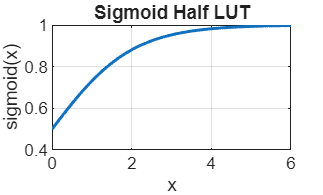


%% =========================
% 6) 畫圖
%% =========================
figure;
plot(x_sig, y_sig, 'LineWidth', 1.5); grid on;
title('Sigmoid Half LUT');
xlabel('x'); ylabel('sigmoid(x)');

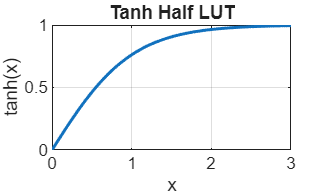


figure;
plot(x_tanh, y_tanh, 'LineWidth', 1.5); grid on;
title('Tanh Half LUT');
xlabel('x'); ylabel('tanh(x)');

## 驗證 Coding

% ============================================================
% (VI) 修正後的混合驗證：動態建立 TempNet
% ============================================================
numSamples = size(XTest4, 4);
allCats = categories(YTest); 
YPred_manual_Q = categorical(repmat(allCats(1), numSamples, 1));

% 3. 提取量化後的參數 (整數碼轉回的浮點)
% ------------------------------
% 依 layer 名稱取值，插入 quant layer 後也不會因編號改變而抓錯層。
manualLayers = netQ.Layers;
L_conv1 = manualLayers(strcmp({manualLayers.Name}, "conv1"));
W1_Q = L_conv1.Weights;
B1_Q = L_conv1.Bias;
BN1 = manualLayers(strcmp({manualLayers.Name}, "bn1"));
Offset1 = BN1.Offset; Scale1 = BN1.Scale;
TMean1 = BN1.TrainedMean; TVar1 = BN1.TrainedVariance; Eps1 = BN1.Epsilon;
% ------------------------------
L_conv2 = manualLayers(strcmp({manualLayers.Name}, "conv2"));
W2_Q = L_conv2.Weights;
B2_Q = L_conv2.Bias;
BN2 = manualLayers(strcmp({manualLayers.Name}, "bn2"));
Offset2 = BN2.Offset; Scale2 = BN2.Scale;
TMean2 = BN2.TrainedMean; TVar2 = BN2.TrainedVariance; Eps2 = BN2.Epsilon;
%pool1/pool2
poolSize = [1, 10];
stride   = [1, 8];
% ------------------------------
L_conv3 = manualLayers(strcmp({manualLayers.Name}, "conv3"));
W3_Q = L_conv3.Weights;
B3_Q = L_conv3.Bias;
BN3 = manualLayers(strcmp({manualLayers.Name}, "bn3"));
Offset3 = BN3.Offset; Scale3 = BN3.Scale;
TMean3 = BN3.TrainedMean; TVar3 = BN3.TrainedVariance; Eps3 = BN3.Epsilon;
% ------------------------------
% gru
sigmoid_lut = load_sigmoid_half_lut("sigmoid_half_lut.mem");
tanh_lut = load_sigmoid_half_lut("tanh_half_lut.mem"); % 手算 GRU 也使用硬體 tanh LUT
gru_param = extract_gru_params(netQ_weight); % 使用量化後 GRU 權重，而非原始浮點權重
% ------------------------------
% FC1
L_fc1 = manualLayers(strcmp({manualLayers.Name}, "fc_1"));
fc1_w = L_fc1.Weights;
fc1_b = L_fc1.Bias;
%bn_2
BN_2 = manualLayers(strcmp({manualLayers.Name}, "bn_2"));
Offset_2 = BN_2.Offset; Scale_2 = BN_2.Scale;
TMean_2 = BN_2.TrainedMean; TVar_2 = BN_2.TrainedVariance; Eps_2 = BN_2.Epsilon;
% FC2
L_fc2 = manualLayers(strcmp({manualLayers.Name}, "fc_out"));
fc2_w = L_fc2.Weights;
fc2_b = L_fc2.Bias;

fprintf("Testing final Accuracy...\n");

Testing final Accuracy...


testNum = min(2600, numSamples);



for i = 1:testNum
    % ------------------------------
    % --- [手刻層] ---
    % ------------------------------

    % input
    currentX = XTest4(:,:,1,i); 
    % 先做量化
    x_in = quantize_layer(currentX,Fa_in);
    % ------------------------------
    % conv1
    x_conv_raw = conv2d_layer(x_in, W1_Q, B1_Q); 
    x_conv = quantize_layer(x_conv_raw,F_act.conv1);
    % bn1
    x_bn_raw = batchnorm_layer(x_conv, Offset1, Scale1, TMean1, TVar1, Eps1);
    x_bn = quantize_layer(x_bn_raw, F_act.bn1);
    % relu1
    x_relu_raw = relu_layer(x_bn);
    x_relu = quantize_layer(x_relu_raw, F_act.relu1);
    % ------------------------------
    % conv2
    x_conv_raw2 = conv2d_layer(x_relu, W2_Q, B2_Q); 
    x_conv2 = quantize_layer(x_conv_raw2,F_act.conv2);
    % bn2
    x_bn_raw2 = batchnorm_layer(x_conv2, Offset2, Scale2, TMean2, TVar2, Eps2);
    x_bn2 = quantize_layer(x_bn_raw2, F_act.bn2);
    % relu2
    x_relu_raw2 = relu_layer(x_bn2);
    x_relu2 = quantize_layer(x_relu_raw2, F_act.relu2);
    %pool1
    x_pool1_raw = pool_layer(x_relu2,poolSize,stride);
    x_pool1 = quantize_layer(x_pool1_raw, F_act.max_pooling1);
    % ------------------------------
    % conv3
    x_conv_raw3 = conv2d_layer(x_pool1, W3_Q, B3_Q); 
    x_conv3 = quantize_layer(x_conv_raw3,F_act.conv3);
    % bn3
    x_bn_raw3 = batchnorm_layer(x_conv3, Offset3, Scale3, TMean3, TVar3, Eps3);
    x_bn3 = quantize_layer(x_bn_raw3, F_act.bn3);
    % relu3
    x_relu_raw3 = relu_layer(x_bn3);
    x_relu3 = quantize_layer(x_relu_raw3, F_act.relu3);
    %pool2
    x_pool2_raw = pool_layer(x_relu3,poolSize,stride);
    x_pool2 = quantize_layer(x_pool2_raw, F_act.max_pooling2);
    % ------------------------------
    % reshape
    x_reshape = reshape_layer(x_pool2);
    % gru
    x_gru = gru_layer(x_reshape, gru_param, sigmoid_lut, tanh_lut);
    % flatten
    x_flatten_raw = flatten_layer(x_gru);
    x_flatten = quantize_layer(x_flatten_raw, F_act.flatten_reshape);
    % ------------------------------
    % fc1
    x_fc_1_raw = FC_layer(x_flatten, fc1_w, fc1_b);
    x_fc_1 = quantize_layer(x_fc_1_raw, F_act.fc_1);
    % relu_fc
    x_relu_fc_raw = relu_layer(x_fc_1);
    x_relu_fc = quantize_layer(x_relu_fc_raw, F_act.relu_fc);
    % bn_2
    x_bn_2_raw = batchnorm_flatten_layer(x_relu_fc, Offset_2, Scale_2, TMean_2, TVar_2, Eps_2);
    x_bn_2 = quantize_layer(x_bn_2_raw, F_act.bn_2);
    %fc_out
    x_fc_out_raw = FC_layer(x_bn_2, fc2_w, fc2_b);
    x_fc_out = quantize_layer(x_fc_out_raw, F_act.fc_out);

    pred_scores = softmax_layer(x_fc_out);
    
    % 判定類別
    [~, maxIdx] = max(pred_scores);
    YPred_manual_Q(i) = allCats(maxIdx);
    
    % 顯示進度
    if mod(i, 200) == 0, fprintf("Progress: %d/%d\n", i, numSamples); end
end

Progress: 200/119075
Progress: 400/119075
Progress: 600/119075
Progress: 800/119075
Progress: 1000/119075
Progress: 1200/119075
Progress: 1400/119075
Progress: 1600/119075
Progress: 1800/119075
Progress: 2000/119075
Progress: 2200/119075
Progress: 2400/119075
Progress: 2600/119075



acc_manual_Q = mean(YPred_manual_Q(1:testNum) == YTest(1:testNum));
fprintf("\nOriginal Test Accuracy: %.2f%%\n", acc * 100);


Original Test Accuracy: 96.70%


fprintf("Quantize Test Accuracy: %.2f%%\n", accQ * 100);

Quantize Test Accuracy: 96.70%


fprintf("Simulate Test Accuracy: %.2f%%\n", acc_manual_Q * 100);

Simulate Test Accuracy: 94.69%


## Quantize Function

function Y = quantize_layer(X, Fa)
    total_bits = 16;
    scale = 2^Fa;

    Xi = floor(X * scale);

    max_int = 2^(total_bits-1) - 1;
    min_int = -2^(total_bits-1);
    Xi = min(max(Xi, min_int), max_int);

    Y = Xi / scale;
end

## Convolution Function

% 卷積層
function Y = conv2d_layer(X, W, b)
    % 功能：手動實現 2D 卷積運算 (模擬硬體 PE 運算)
    % X: 輸入資料 [H, W, Cin] -> 例如第一層為 [21, 160, 1]
    % W: 權重矩陣 [kH, kW, Cin, Cout] -> 例如第一層為 [2, 5, 1, 21]
    % b: 偏差值 [1, 1, Cout] -> 例如第一層為 [1, 1, 21]
    
    % 1. 取得維度資訊
    [H, Win, Cin] = size(X); % 輸入資料
    [kH, kW, ~, Cout] = size(W); % 捲積
    
    % 2. 計算輸出尺寸 (基於 Stride=1, Padding=0)
    % 公式: Out = (In - Kernel + 2*Pad) / Stride + 1
    outH = H - kH + 1; % 第一層為 21-2+1 = 20
    outW = Win - kW + 1; % 第一層為 160-5+1 = 156
    
    % 3. 初始化輸出矩陣
    Y = zeros(outH, outW, Cout);
    
    % 4. 執行多重迴圈模擬硬體 MAC (乘加) 過程
    for co = 1:Cout % 遍歷輸出通道 (Filters)，模擬 21 個 PE
        for i = 1:outH % 遍歷空間高度
            for j = 1:outW % 遍歷空間寬度
                
                % 初始化累加器，先存入 Bias
                acc = b(co); 
                
                % 執行 2D 視窗內的卷積運算
                for ci = 1:Cin % 輸入通道 (第一層為 1)
                    for m = 1:kH % 卷積核高度 (2)
                        for n = 1:kW % 卷積核寬度 (5)
                            % 取得輸入像素與對應權重
                            pixel = X(i + m - 1, j + n - 1, ci);
                            weight = W(m, n, ci, co);
                            
                            % 累加乘法結果 (MAC 運算)
                            acc = acc + (pixel * weight);
                        end
                    end
                end
                
                % 儲存該位置的最終結果
                Y(i, j, co) = acc;
            end
        end
    end
end

## Batch Normalization Function

% BN layer
function Y = batchnorm_layer(X, Offset, Scale, TrainedMean, TrainedVariance, Epsilon)
    [H, W, Cout] = size(X);
    Y = zeros(H, W, Cout);
    
    for c = 1:Cout
        % 提取通道參數
        m = TrainedMean(c);
        v = TrainedVariance(c);
        s = Scale(c);
        o = Offset(c);
        denom = sqrt(v + Epsilon);
        
        for i = 1:H
            for j = 1:W
                % 標準 BN 公式: ((X - Mean) / sqrt(Var + Eps)) * Scale + Offset
                Y(i, j, c) = ((X(i, j, c) - m) / denom) * s + o;
            end
        end
    end
end

function Y = batchnorm_flatten_layer(X, Offset, Scale, TrainedMean, TrainedVariance, Epsilon)
% X : [F, B]
% Y : [F, B]

    if isvector(X)
        X = reshape(X, [], 1);
    end

    F = size(X,1);
    B = size(X,2);

    Y = zeros(F, B);

    for f = 1:F
        m = TrainedMean(f);
        v = TrainedVariance(f);
        s = Scale(f);
        o = Offset(f);
        denom = sqrt(v + Epsilon);

        for b = 1:B
            Y(f,b) = ((X(f,b) - m) / denom) * s + o;
        end
    end
end

## Relu Function

% relu function
function Y = relu_layer(X)
    [H, W, Cout] = size(X);
    Y = zeros(H, W, Cout);
    for c = 1:Cout
        for i = 1:H
            for j = 1:W
                val = X(i, j, c);
                % 負數歸零
                if val < 0
                    val = 0;
                end
                Y(i, j, c) = val;
            end
        end
    end
end

## Maxpooling Function

function Y = pool_layer(X, poolSize, stride)
    % X: 輸入 [H, W, C]
    % poolSize: [pH, pW] -> [1, 10]
    % stride: [sH, sW] -> [1, 8]
    
    [inH, inW, C] = size(X);
    pH = poolSize(1); pW = poolSize(2);
    sH = stride(1);   sW = stride(2);
    
    % 計算輸出尺寸
    outH = floor((inH - pH) / sH) + 1;
    outW = floor((inW - pW) / sW) + 1;
    
    Y = zeros(outH, outW, C);
    
    for c = 1:C
        for i = 1:outH
            for j = 1:outW
                % 計算目前視窗在輸入矩陣中的座標
                h_start = (i-1)*sH + 1;
                h_end   = h_start + pH - 1;
                w_start = (j-1)*sW + 1;
                w_end   = w_start + pW - 1;
                
                % 提取視窗並找最大值
                window = X(h_start:h_end, w_start:w_end, c);
                Y(i, j, c) = max(window(:));
            end
        end
    end
end

## Reshape Function

function Y = reshape_layer(X)
    if isa(X, 'dlarray')
        X = stripdims(X);
    end

    if ndims(X) == 3
        X = reshape(X, size(X,1), size(X,2), size(X,3), 1);
    end

    B = size(X, 4);
    X = permute(X, [3 1 2 4]);
    Y = reshape(X, 15, [], B);
end

## 載入設定好的函數

function lut = load_sigmoid_half_lut(filename)
% 讀取 hex 格式的 sigmoid half LUT
% 輸出 lut: 1xN double，內容為 0~127 的整數

    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open LUT file: %s', filename);
    end

    lut = [];
    line = fgetl(fid);
    while ischar(line)
        line = strtrim(line);
        if ~isempty(line)
            lut(end+1) = hex2dec(line); %#ok<AGROW>
        end
        line = fgetl(fid);
    end
    fclose(fid);

    lut = double(lut);
end

function y = sigmoid_from_half_lut(x, lut)
% x   : 任意大小 double matrix
% lut : 1xN，half sigmoid LUT，內容為 Q1.7 整數 (0~127)
%
% 輸出 y : 與 x 同大小，double，數值範圍約 0~1
%
% half LUT 假設對應範圍 [0, 6]

    N = length(lut);
    y = zeros(size(x));

    for i = 1:numel(x)
        xi = x(i);

        sign_neg = (xi < 0);
        xa = abs(xi);

        % clamp 到 [0, 6]
        if xa > 6
            xa = 6;
        end

        % 對應到 LUT index: 0~6 -> 1~N
        idx = round(xa / 6 * (N - 1)) + 1;

        % LUT 取值，Q1.7 -> real
        val = lut(idx) / 128;

        if sign_neg
            % sigmoid(-x) = 1 - sigmoid(x)
            % 但你的 LUT 最大只到 127/128，所以這裡也保持同樣邏輯
            y(i) = 1 - val;
        else
            y(i) = val;
        end
    end
end

lut = load_sigmoid_half_lut('sigmoid_half_lut.mem');

x = linspace(-8, 8, 1000);
y_true = 1 ./ (1 + exp(-x));
y_lut  = sigmoid_from_half_lut(x, lut);

err = abs(y_true - y_lut);
%fprintf('Max abs error = %.6f\n', max(err));
%fprintf('Mean abs error = %.6f\n', mean(err));

## GRU 取值 Function

function gru_param = extract_gru_params(netLike)
% 從 net 或 netQ 中抓出 GRU 層參數
% 對應 gruLayer(9,"OutputMode","sequence")

    layers = netLike.Layers;
    idx = find(strcmp({layers.Name}, "gru"), 1);

    if isempty(idx)
        error("Cannot find GRU layer named 'gru'.");
    end

    L = layers(idx);

    H = L.NumHiddenUnits;   % 9

    % MATLAB GRU 權重3H x C / 3H x H / 3H x 1
    W = L.InputWeights;       % [3H, C]
    U = L.RecurrentWeights;   % [3H, H]
    b = L.Bias;               % [3H, 1]

    % 拆成 z / r / h 三組
    gru_param.Wr = W(1:H, :);
    gru_param.Wz = W(H+1:2*H, :);
    gru_param.Wh = W(2*H+1:3*H, :);

    gru_param.Ur = U(1:H, :);
    gru_param.Uz = U(H+1:2*H, :);
    gru_param.Uh = U(2*H+1:3*H, :);

    gru_param.br = reshape(b(1:H), H, 1);
    gru_param.bz = reshape(b(H+1:2*H), H, 1);
    gru_param.bh = reshape(b(2*H+1:3*H), H, 1);
end

## GRU Function

function Y = gru_layer(X, param, sigmoid_lut, tanh_lut)
% X: [C T B]
% param: struct with
%   Wz, Uz, bz
%   Wr, Ur, br
%   Wh, Uh, bh
% sigmoid_lut: 從 sigmoid_half_lut.mem 讀進來的 1xN LUT
%
% 輸出:
%   Y: [H T B]
%
% 對應 gruLayer(H, "OutputMode","sequence")
% 但 z gate / r gate 使用 LUT sigmoid

    [C, T, B] = size(X);
    H = size(param.Wz, 1);

    h = zeros(H, B);
    Y = zeros(H, T, B);

    for t = 1:T
        xt = reshape(X(:, t, :), C, B);

        % -------------------------
        % update gate z
        % -------------------------
        z_pre = param.Wz * xt + param.Uz * h + param.bz;
        z = sigmoid_from_half_lut(z_pre, sigmoid_lut);

        % -------------------------
        % reset gate r
        % -------------------------
        r_pre = param.Wr * xt + param.Ur * h + param.br;
        r = sigmoid_from_half_lut(r_pre, sigmoid_lut);

        % -------------------------
        % candidate hidden state
        % -------------------------
        a = param.Wh * xt + param.Uh * (r .* h) + param.bh;
        h_tilde = tanh_from_half_lut(a, tanh_lut); % 與未來 RTL 的 Q1.7 LUT 一致

        % -------------------------
        % hidden update
        % -------------------------
        h = (1 - z) .* h_tilde + z .* h;

        Y(:, t, :) = reshape(h, H, 1, B);
    end
end

## Flatten Function

function Y = flatten_layer(X)
% X : [C T B]
% Y : [C*T , B]

    C = size(X,1);
    T = size(X,2);
    B = size(X,3);

    Y = reshape(X, C*T, B);
end

## Fully Connected Function

function Y = FC_layer(X, W, b)
% X : [inFeatures, B] 或 [inFeatures, 1]
% W : [outFeatures, inFeatures]
% b : [outFeatures, 1]
% Y : [outFeatures, B]

    if isvector(X)
        X = reshape(X, [], 1);
    end

    Y = W * X + b;
end

function Y = softmax_layer(X)
% X : [numClasses, B]
% Y : [numClasses, B]

    if isvector(X)
        X = reshape(X, [], 1);
    end

    % 數值穩定版 softmax
    Xmax = max(X, [], 1);
    Xs = X - Xmax;

    expX = exp(Xs);
    Y = expX ./ sum(expX, 1);
end

% Tanh half-LUT：正半邊存 [0,3]，負值利用 tanh(-x)=-tanh(x)。
function y = tanh_from_half_lut(x, lut)
    N = length(lut);
    y = zeros(size(x));

    for i = 1:numel(x)
        xi = x(i);
        xa = min(abs(xi), 3);
        idx = round(xa / 3 * (N - 1)) + 1;
        val = lut(idx) / 128;

        if xi < 0
            y(i) = -val;
        else
            y(i) = val;
        end
    end
end

numSamples = size(XTest4, 4);

fid = fopen("test_inputs_q12.bin", "w", "ieee-le");

for i = 1:numSamples
    X = XTest4(:,:,:,i);

    % 必須沿用專案目前完全相同的量化函式
    X_int = QuantizeToInt(X, q.total_bits, Fa_in, q.mode);

    % 每筆固定3360個signed 16-bit
    fwrite(fid, int16(X_int(:)), "int16");
end

fclose(fid);